# Tasks 3

## Loading up an image dataset

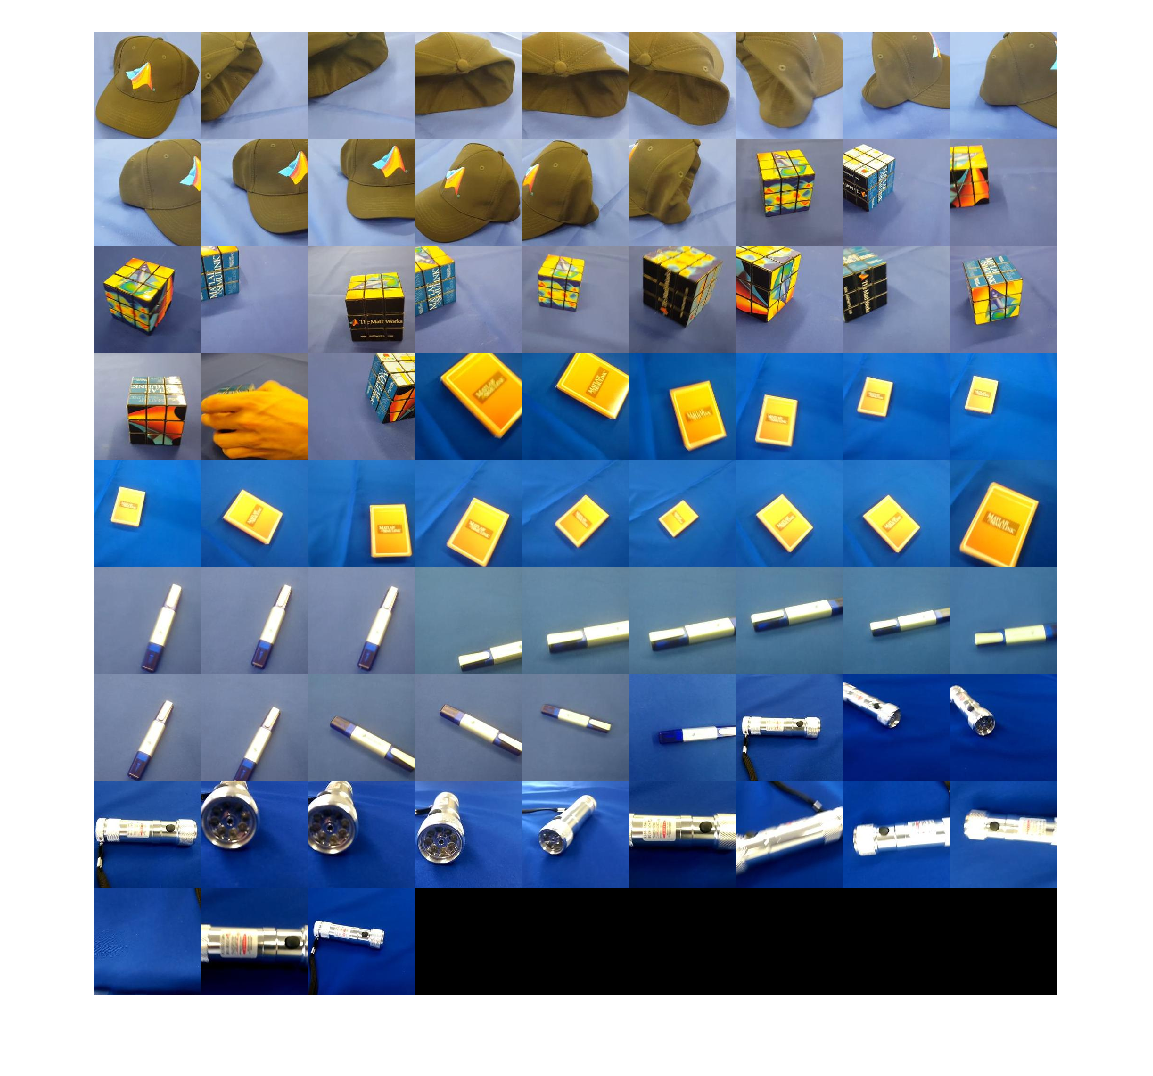

The MerchData dataset (available on Moodle) contains colour images (size 227*227*3) of different objects, organised between appropriately named folders. The challenge is to use ML to classify images between the different categories of object which they show and you can assume the dataset is clean and ready for use in ML tasks. Unzip the dataset and add code below to load it as an `imageDatastore` using the folder names as class labels:

(**Sanity check**: your `imageDatastore` should contain 75 images)

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

imds = imageDatastore('MerchData','IncludeSubfolders', true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_0.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_123.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_148.jpg'
                               ... and 72 more
                              }
                     Folders: {
                              '/MATLAB Drive/Examples/mainDir/lab work/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 72 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @r



% write your code on the lines below:



## Splitting an image dataset

Divide your `imageDatastore` object into two smaller `imageDatastore` objects, one containing a random 60% of the images in each class for use in training, and one containing the remaining 40% of the images in each class for use in testing:

(**Sanity check**: your training `imageDatastore` should contain 45 images and your testing `imageDatastore` should contain 30 images)

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

%shuffles the images and splits them into 60/40 ratio into seprate arrays for acurate data sampling

## Reading one image

Load up the first image in your training `imageDatastore` and display it using `imshow()`. Now load and display the first image for a second time and convince yourself you are definitely seeing the same image:

(**Sanity check**: if you see different images, remember that subsequent calls to the `read()` method continue from the endpoint of the previous call; generally this behaviour is very useful (we'll use it lots in later tasks), but remember you can reset the endpoint by calling the `reset()` method or read specific images by calling the `readimage()` method with a specific index, e.g. 1 for the first image, 2 for the second image, etc.)

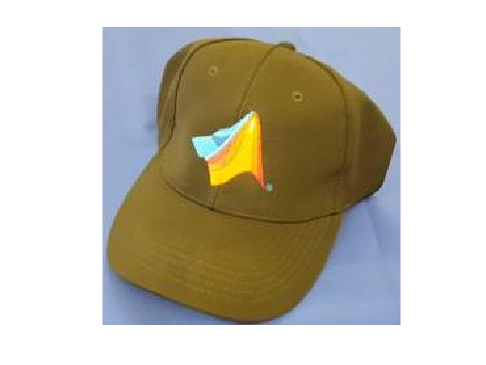


%first indexed image is shown 
im = training.readimage(1);
imshow(im);

training.reset;

## Image features I

Functions like `fitcknn()` will accept tables or normal 2D arrays of data, but they won't accept raw images. If we want to do classification problems with images then it's our job to extract a series of features from each image, and use them them to build up a tabular dataset of the kind we're used to working with (one example per row, individual feature values in individual columns, a separate array of class labels). An obvious first option when working with images that are all the same size (as the MerchData images are) is to just take *all* of the different colour channel values as features. So one green, one red and one blue brightness value per image pixel, laid out in a really long horizontal 1D array (for a single image). Adding such arrays together, each one beneath the last, we would end up with a suitable datset: one example(image) per row, individual feature values(brightnesses) in individual columns.

In practice though, this doesn't tend to good classification performance. In a nutshell (see slides for more discussion): we end up with too many numbers, and no guarantee that those numbers relate to the same things in any two different examples.

Write a simple expression to calculate the total number of brightness values there are in the first image in your training `imageDatastore`:

(**Hint**: you can call the `size()` function to get the numbers you need to multiply together to get the right answer; even for a relatively small image (like this one), you should get a pretty big number)


%returns the size of the array and gets the product of it 
totalCBrightness = numel(im)

totalCBrightness = 154587

size(im);

ans =    227   227     3


total = size(im,1) * size(im,2) *size(im,3)

total = 154587

## Image features II

We want to reduce down the number of features we extract from every image, and we need to aim for features that will be comparable between different examples. Almost all approaches to this problem start off by converting colour images to greyscale, or "black & white", images (overall brightness at each pixel, rather than separate r/g/b brightnesses). The basic idea is to concentrate on the underlying structures that are visible in the image, rather than the particular wavelengths of light they happen to reflect (see slides for more discussion).

Use Matlab's `im2gray()` function to convert the first image in your training `imageDatastore` to black and white, and write a simple expression to calculate the total number of brightness values it now contains:

(**Sanity check**: you should find you have one third of the number of values you had in the original colour version)

im =  im2gray(im);

totalBrightness = numel(im)

totalBrightness = 51529

## Indexing images: refresher

You've done this before, but just as a little warmup for indexing images... Load the first image in your training `imageDatastore` again, convert it to greyscale again, and then make sure you can change the brightness values for the pixel on the 100th row down and 50th column across to be 255. Display the image again, and check you can see the pixel you changed (it should be white):

(**Sanity check**: this could be a good moment to briefly look over the work you did on interacting with images in the Matlab Fundamentals - if you're not sure about anything then ask for help)

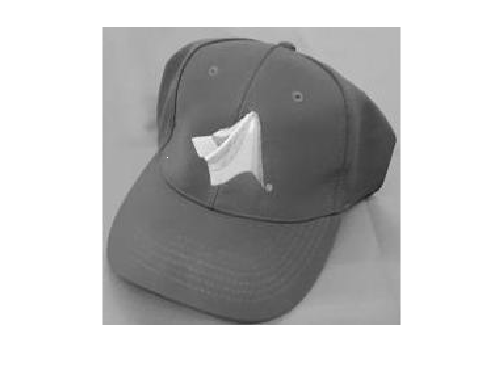

im(100,50) = 255;
imshow(im)

## Image brightness I

Now let's try to extract some specific feature values from each image, and construct a ML problem. We'll start off *very* simply: by extracting the average brightness from each image. So we'll have a single feature for each image (average brightness in a column all by itself), which is fair to compare between different images (even if they have different sizes) but still very simplistic. In all likelihood, this single feature will turn out not to contain enough information for us to get very good classification performance, but it's a fair start, and we'll gradually extend and improve our approach in future weeks.

Sum up all of the brightness values in the black and white version of the first image in your training `imageDatastore`, and divide them by the total number of pixels in that image to give a single number measuring the average brightness per pixel:

(**Sanity check**: if you get lots of numbers back (rather than just one) remember most of Matlab's built in functions act separately on individual columns if you pass them 2D arrays; remember that you can use a *single* `(1:1:end)` index in order to get the contents of a 2D (or ND) array back as a single long horizontal 1D array; remember divisions happen before multiplications if you're calculating the number of pixels in the same expression; the average should be somewhere in the allowable brightness range 0-255)

avgBrightnessPP = totalBrightness \ sum(im(1:1:end))

avgBrightnessPP = 125.3101

## Image brightness II

Now reuse your code from the previous task to extend the `get_brightness()` function stub so that for any image passed in, it converts it to greyscale and calculates and returns the average brightness measure. Add code below to pass the first image in your training `imageDatastore` to your new function and convince yourself that it returns the correct answer:

(**Sanity check**: the answer you get back from your function should match the number you got in the previous task)


%get_brightness(im)



## Extracting training data

The `Labels` property of your training `imageDatastore` contains the class labels for each of your training images, in order. Copy it into a variable called `train_labels`. Now by looping over the images in your training `imageDatastore`, and calling your `get_brightness()` method with each one, construct an array of corresponding brightness features called `train_examples`: If you're struggling, consider checking the Matlab fundamentals for a reminder of how you can grow arrays downwards, checking the reusable code in the lecture slides, or having a play around in the Command Window to remind yourself:

(**Sanity check**: `train_examples` should be a vertical 1D array, just like `train_labels`, and with the same number of elements; if you get something with fewer elements consider whether you need to call `reset()` on your training `imageDatastore`)

train_labels = training.Labels;

train_examples = [];
%empty array used for growing in a loop

%loops until no indexed data is present
while hasdata(training)
    im = training.read();
    train_examples(end+1,:) = get_brightness(im);
    %adds the sum of the function to the next row on the first column
end


## Train and evaluate an image classifier

Use the `train_examples` and `train_labels` arrays you created in the previous task to call `fitcknn()` and train a k-NN classifier with k=3 neighbours. Next, build `test_examples` and `test_labels` arrays from your testing data in just the same way you did for the previous task, and use these new arrays to evaluate your classifier's performance by computing a confusion matrix and overall classification accuracy. 

(**Sanity check**: you should expect better performance than a classifier that predics classes at random (which would give 20% with 5 classes) but nothing great; around 46.7% accuracy with this initial very simple image feature (assuming you preserved the random number seed at the start of the script); we'll work on developing a gradually more sophisticated and better performing approach to image classification over the coming weeks)

test_labels = testing.Labels;

test_examples = [];

while hasdata(testing)
    im = testing.read();
    test_examples(end+1,:) = get_brightness(im);
end

m_knn = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);

predictions = predict(m_knn,test_examples);
    
[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 46.6667

## Extension task: implementing conversion to greyscale

As a simple first step: extend the `my_im2gray()` function stub so that for any image passed in it converts it to greyscale by summing up the three colour channel components at each pixel coordinate, each weighted by a factor of 1/3 (or a third). Add code below to show how your first training image looks after being passed to your new function:

    training.reset;
    im = training.readimage(1)

im = 227×227×3 uint8 array
im(:,:,1) =

   163   163   163   164   164   165   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161   161   161   162   161   161   160   160   161   161   162   161   161   161   160   160   159   159   159   160   160   160   161   163   164   165   165   168   168   170   170   171   171   171   171   170   170   168   168   167   167   165   165   162   161   161   160   159   159   160   161   163   165   166   166   166   166   167   167   168   168   168   168   168   168   168   166   170   168   168   169   170   172   175   177   172   171   170   169   169   169   169   169   172   171   171   170   168   167   165   165   168   168   168   168   168   168   168   168   172   172   172   173   173   174   174   174   174   174   174   174   174   174   174   175   178   179   178   178   178   179   179   179   181   178   178   175   175   171   169   169

    im1 = im2gray(im);
    %gets each dimension for  

    im = im2double(im);
    R = im(1:1:end, 1:1:end,1);
    G = im(1:1:end, 1:1:end,2);
    B = im(1:1:end, 1:1:end,3);

    

    im  = 0.2989 * R + 0.5870 * G + 0.1140 * B;
    im = im2uint8(im)

im = 227×227 uint8 matrix
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   172   172   172   173   173
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   173   172   172   173   173
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   174   173   173   173   172   173   174
   176   176   177   177   177   178   178   178   178   178   178   17

    im1

im1 = 227×227 uint8 matrix
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   172   172   172   173   173
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   173   172   172   173   173
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   174   173   173   173   172   173   174
   176   176   177   177   177   178   178   178   178   178   178   1

    isequal(im,im1)

ans = logical
   0


    
%     im1 = im2gray(im);
%     sum(im1(1:1:end))

    

%     im  = 0.2989 * R + 0.5870 * G + 0.1140 * B;
%     sum(im(1:1:end))
%     %offical way apparently
% 
%     %im = im2gray(im)
%     %im1 = matlab.images.internal.rgb2gray(im)
%     
%     im2 = (0.2989 * R) + (0.5870 * G) + (0.1140 * B);
%     sum(im2(1:1:end))
%     
%     im3 = 0.3*R + 0.59*G + 0.11*B;
%     sum(im3(1:1:end))
%     
%     im4 = (R/3) + (G/3) + (B/3);
%     sum(im4(1:1:end))
%     
%     im5 = (R+G+B) / 3;
%     sum(im5(1:1:end))
%     
%     im6 = R*0.299 + G*0.587 + B*0.114
%     numel(im6)

Most approaches to greyscale conversion take account of the human visual system's sensitivity to the different colour channels (e.g., we're more sensitive to green light than blue or red light). Call `help` on the built in `im2gray()` function to see the weightings it uses for each colour channel and implement these weightings in your own `my_im2gray()` function. Add code below to show how your first training image looks after being passed to your new function:

% write your code on the lines below



Finally, substitute the call to `im2gray()` in your `get_brightness()` function for a call to your new `my_im2gray()` function and check that your answers to the earlier tasks -- where you classfied the testing dataset based on brightness features -- still give the same classification accuracy. Switch back and forth between calling `im2gray()` and `my_im2gray()` a few times, re-running this live script each time, to convince yourself you are definitely getting the same overall classification accuracy.

(**Sanity check**: to avoid breaking code your wrote earlier in this script you will want your new `my_im2gray()` function to handle the case where it is passed an image that is already greyscale; you just need to return the image without doing anything, but what is the test that lets you detect this case?)